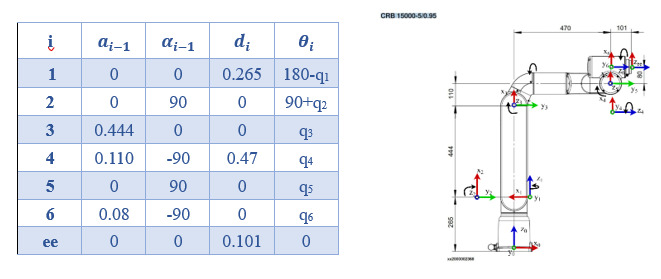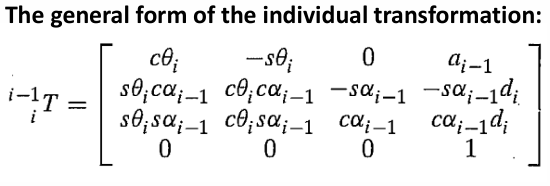

**Check_urdf **

% robot = importrobot('gofa.urdf');
% robot.DataFormat = 'row';
% 
% config = homeConfiguration(robot);
% T0e = getTransform(robot, config, 'tool0', 'base_link');

**DH-Modify**

%% DH_tm
%cho tìm xi thì tuân theo quy tắc bàn tay phải cho zi-> zi+1 
%chỉ xét theo hướng đối với d
clear;clc;
syms q1 q2 q3 q4 q5 q6 d1 d4 dee l3 l4 l6
T01=DH_modify(0,0,d1,pi+q1);

'DH_modify' is not found in the current folder or on the MATLAB path, but exists in:
    D:\HCMUTE_stu_robot_control\Group2\gofa_MATLAB
    D:\TT ROBOT

Change the MATLAB current folder or add its folder to the MATLAB path.

T12=DH_modify(0,pi/2,0,pi/2+q2);
T23=DH_modify(l3,0,0,q3);
T34=DH_modify(l4,-pi/2,d4,q4);
T45=DH_modify(0,pi/2,0,q5);
T56=DH_modify(l6,-pi/2,0,q6);
T6ee=DH_modify(0,0,dee,pi);
T0ee=T01*T12*T23*T34*T45*T56*T6ee;
T0EE=simplify(T0ee);
pee=T0ee(1:3,4);
Ree=T0ee(1:3,1:3);

%validationsyms q1 q2 q3 q4 q5 q6 

%pee_test=double(subs(pee,[q1,q2,q3,q4,q5,q6],[0 0 0 0 0 0]))
%Ree_test=double(subs(Ree,[q1,q2,q3,q4,q5,q6],[0 0 0 0 0 0]))
pee_test = double(subs(pee, ...
 [q1 q2 q3 q4 q5 q6 d1 d4 dee l3 l4 l6], ...
 [0  0  0  0  0  0  0.265 0.47 0.101 0.444 0.11 0.08]))
Ree_test = double(subs(Ree, ...
 [q1 q2 q3 q4 q5 q6 d1 d4 dee l3 l4 l6], ...
 [0  0  0  0  0  0  0.265 0.47 0.101 0.444 0.11 0.08]))



**Jacobian_matrix **

Nếu có DH thì có thể tính bằng cách 

Nếu có n bậc tự do thì J (6xn) với Jv là 3×6và Jω là 3×6

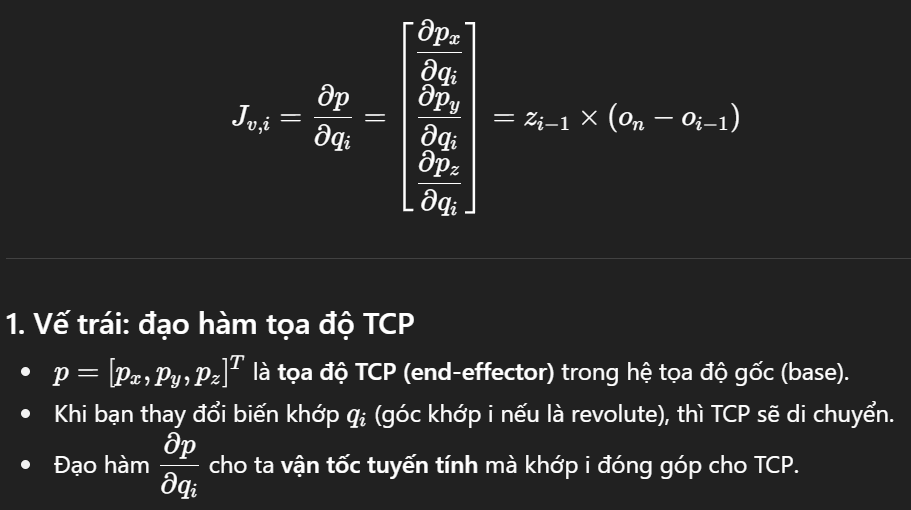

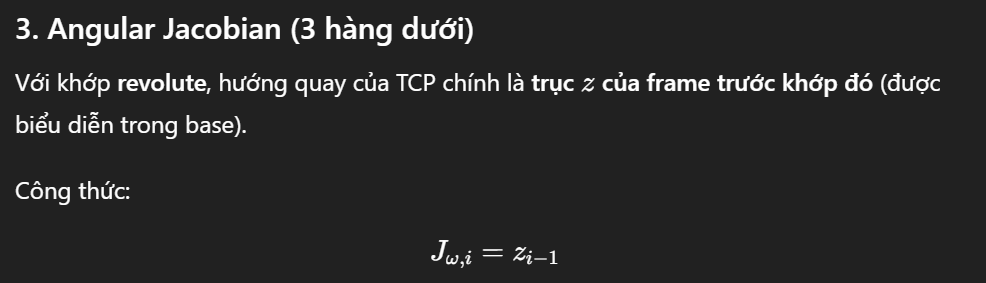

%%Linear jacobian
q=[q1 q2 q3 q4 q5 q6];
J11=simplify(diff(pee(1,1),q1));
J12=simplify(diff(pee(1,1),q2));
J13=simplify(diff(pee(1,1),q3));
J14=simplify(diff(pee(1,1),q4));
J15=simplify(diff(pee(1,1),q5));
J16=simplify(diff(pee(1,1),q6));

J21=simplify(diff(pee(2,1),q1));
J22=simplify(diff(pee(2,1),q2));
J23=simplify(diff(pee(2,1),q3));
J24=simplify(diff(pee(2,1),q4));
J25=simplify(diff(pee(2,1),q5));
J26=simplify(diff(pee(2,1),q6));

J31=simplify(diff(pee(3,1),q1));
J32=simplify(diff(pee(3,1),q2));
J33=simplify(diff(pee(3,1),q3));
J34=simplify(diff(pee(3,1),q4));
J35=simplify(diff(pee(3,1),q5));
J36=simplify(diff(pee(3,1),q6));


%Angular jacobian - Tính theo cột i là của trục i
J41=simplify(T01(1,3));
J51=simplify(T01(2,3));
J61=simplify(T01(3,3));

T02=T01*T12;

J42=simplify(T02(1,3));
J52=simplify(T02(2,3));
J62=simplify(T02(3,3));

T03=T01*T12*T23;

J43=simplify(T03(1,3));
J53=simplify(T03(2,3));
J63=simplify(T03(3,3));

T04=T01*T12*T23*T34;

J44=simplify(T04(1,3));
J54=simplify(T04(2,3));
J64=simplify(T04(3,3));


T05=T01*T12*T23*T34*T45;

J45=simplify(T05(1,3));
J55=simplify(T05(2,3));
J65=simplify(T05(3,3));


T06=T01*T12*T23*T34*T45*T56*T6ee;

J46=simplify(T06(1,3));
J56=simplify(T06(2,3));
J66=simplify(T06(3,3));
